# Isolated Off-board charger for electric vehicles

## Introduction

An **off-board charger** is a type of battery charging system designed to recharge electric vehicles (EVs) or other battery-powered systems. Unlike on-board chargers, which are integrated into the vehicle, off-board chargers are standalone devices. These chargers are commonly found at charging stations or in facilities where high-powered and rapid charging is needed.

Off-board chargers are particularly suited for scenarios requiring high charging power or where space constraints in the vehicle make it impractical to include a high-capacity charging system. They can deliver direct current (DC) power directly to the battery, bypassing the vehicle’s onboard charger. This approach enables faster charging and greater efficiency compared to alternating current (AC) charging, which requires conversion within the vehicle.

In isolated off-board charger, a new DC to AC and AC to DC converter with a transformer are added into the circuit to achieve the isolation. In this model, three LLC resonate converters from previous model are used to achieve DC-AC-AC-DC. 

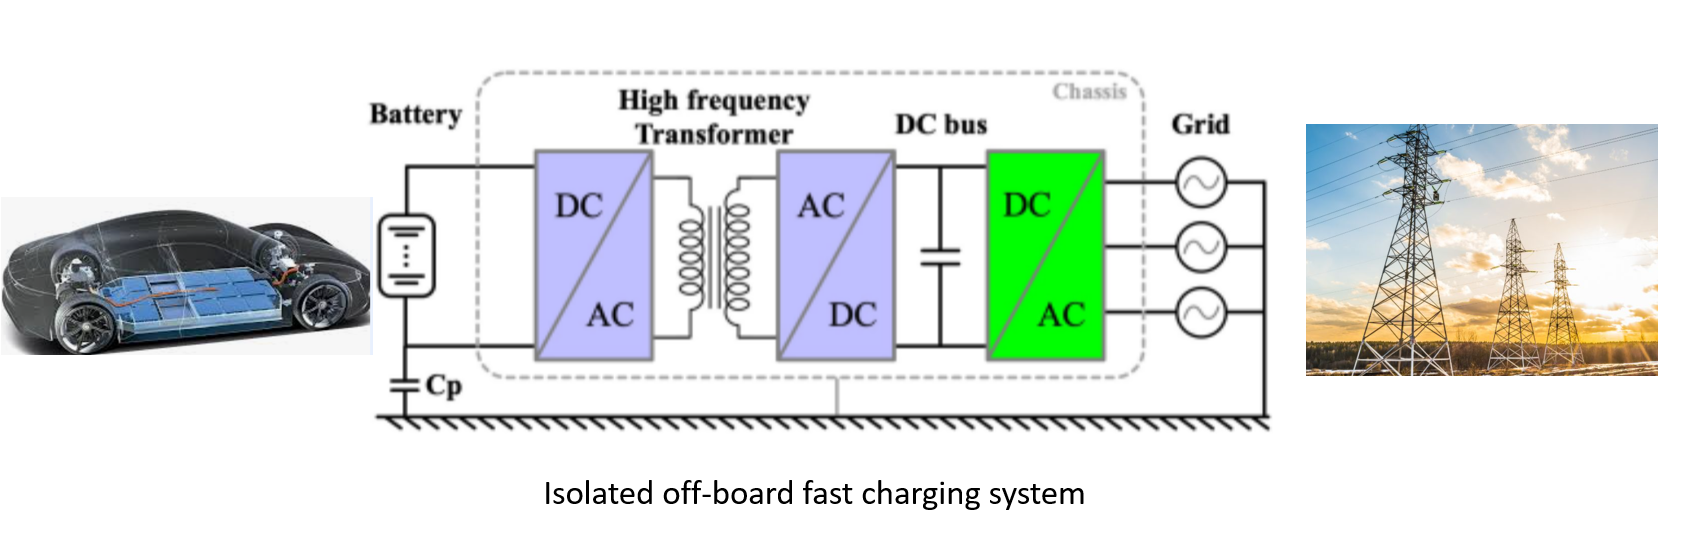 

## Circuit

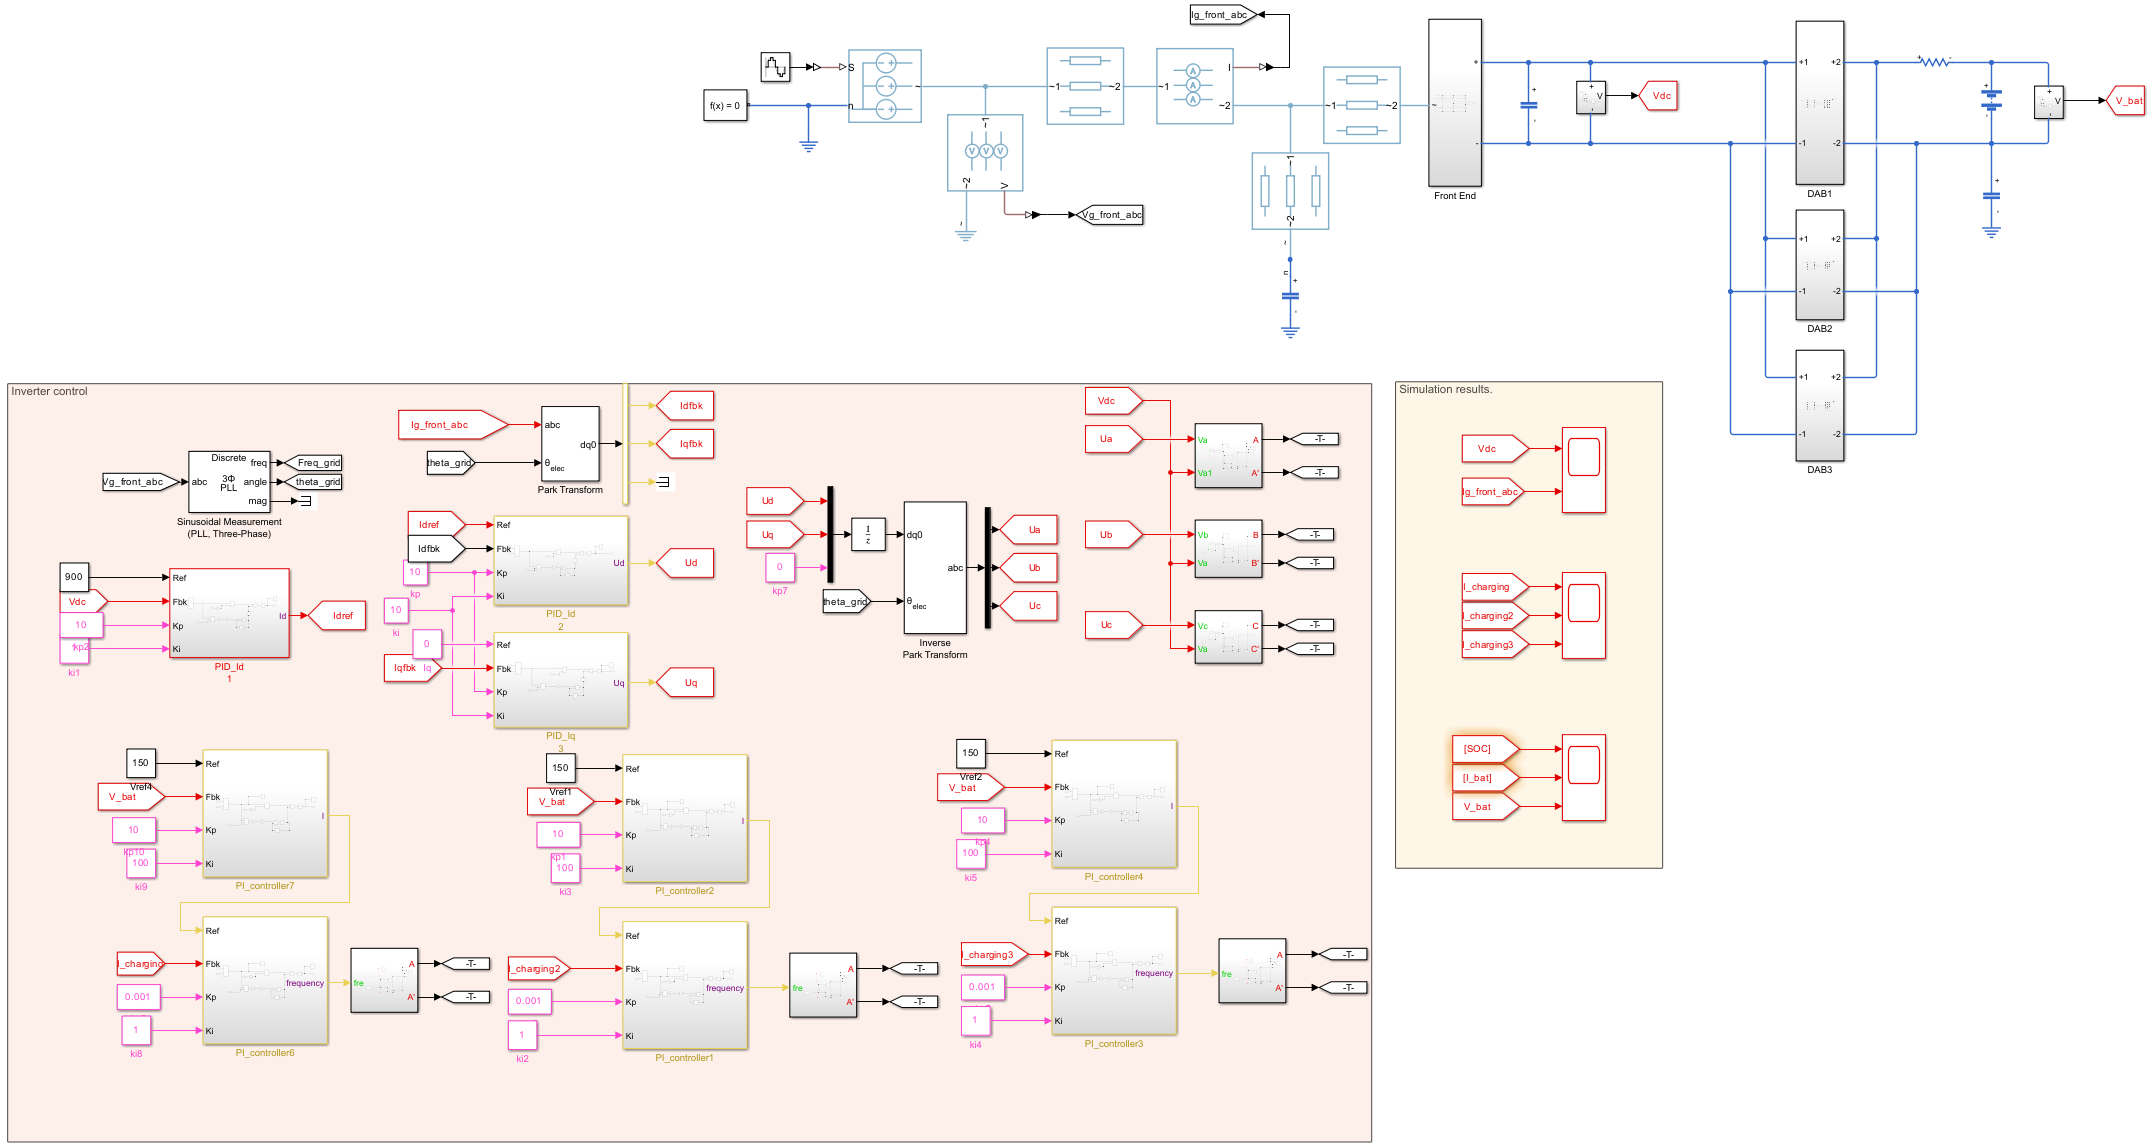

 Click the button the model below to open and familiarize with the model in Simulink.

 
open_system("model\Isooffboard_SSC.slx")
if ~exist('V_ref_isolated','var')
    V_ref_isolated = 900;  
end

Select from the menu below to learn more about different part of the model.

switchRectifier("No Selection");

### Connect to the Grid

For simulation purposes, to ensure the **stability** and **quality** of the power grid, the only requirement for the inverter’s AC output is that its **frequency **matches the grid’s frequency and **phase angle**. A Phase-Locked Loop (PLL) strategy is used to measure grid frequency. At this stage, we do not need to examine the internal principles or operation of the PLL.

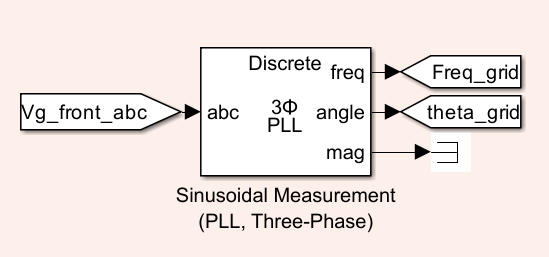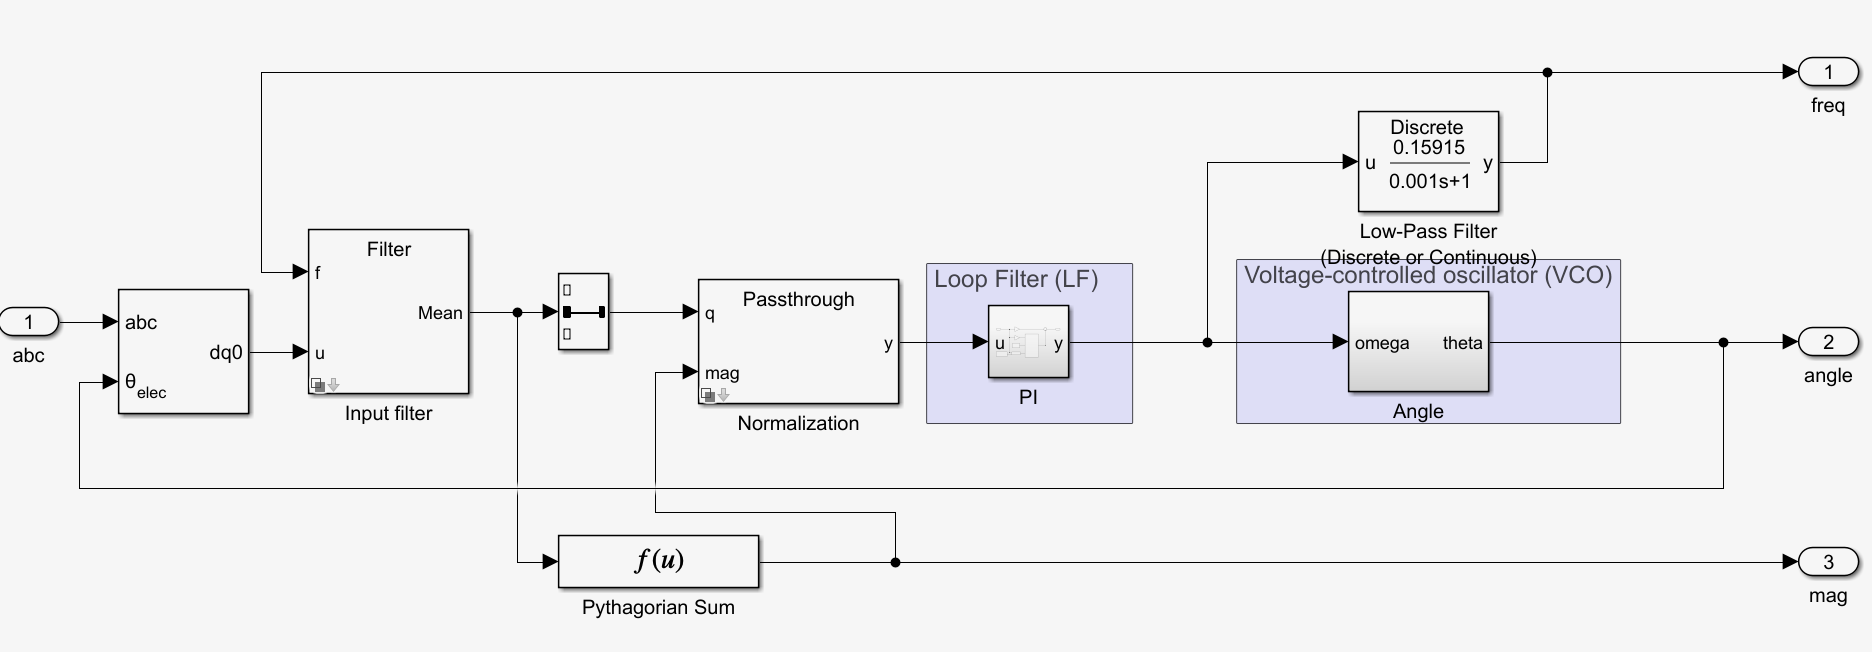

## Control Algorithm

Generally, the control algorithm includes two parts: the **charging current/voltage control** and** inverter and DC bus control.**

 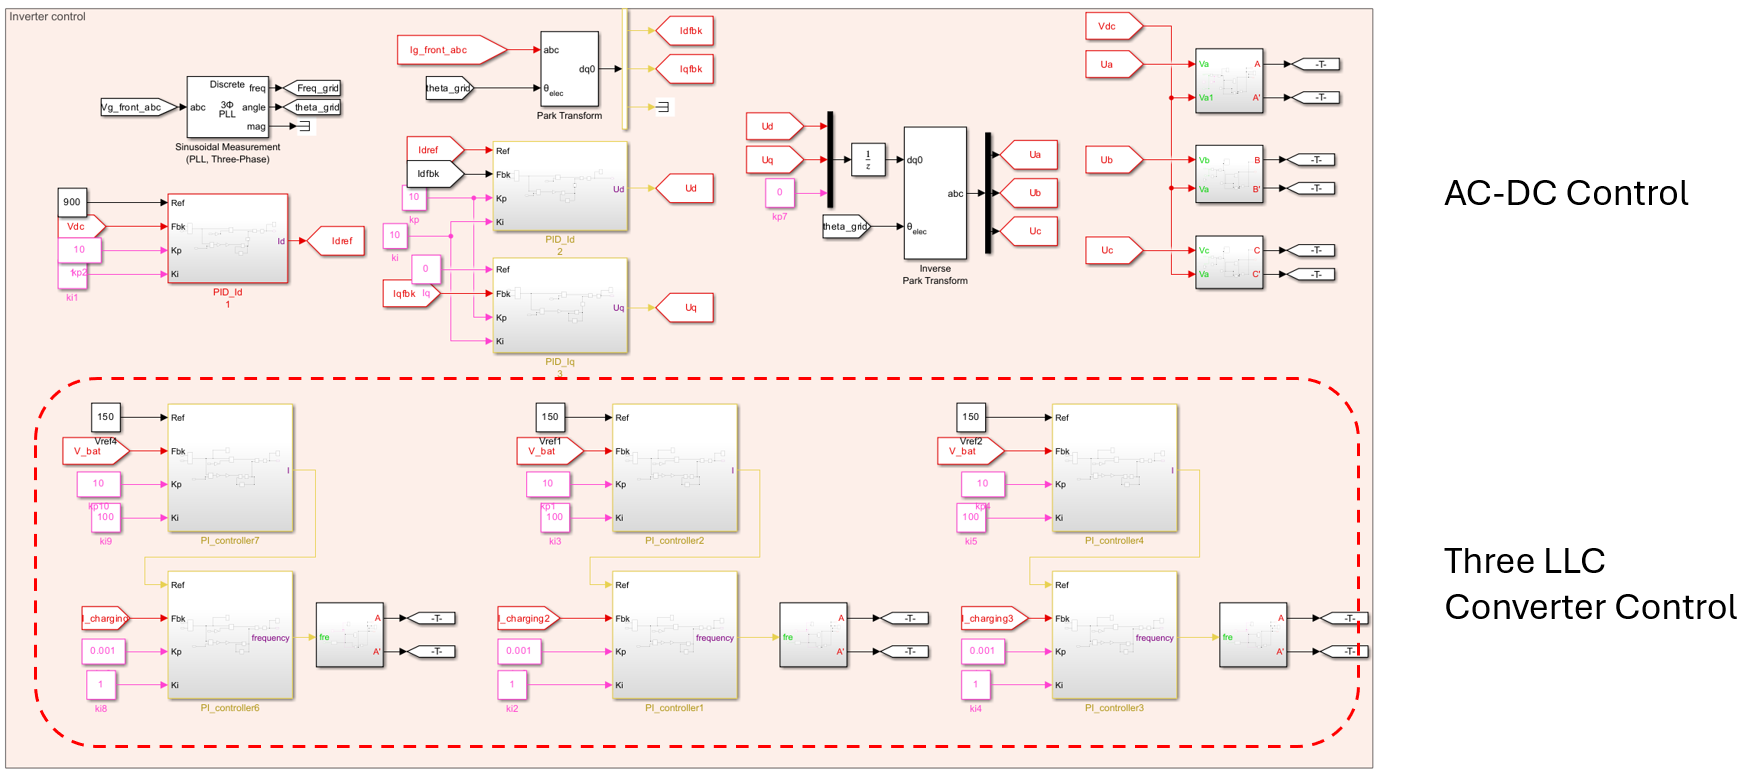

### Charging Current and Voltage Control

The control algorithm are designed for two stages, **constant current** stage and **constant voltage** stage. 

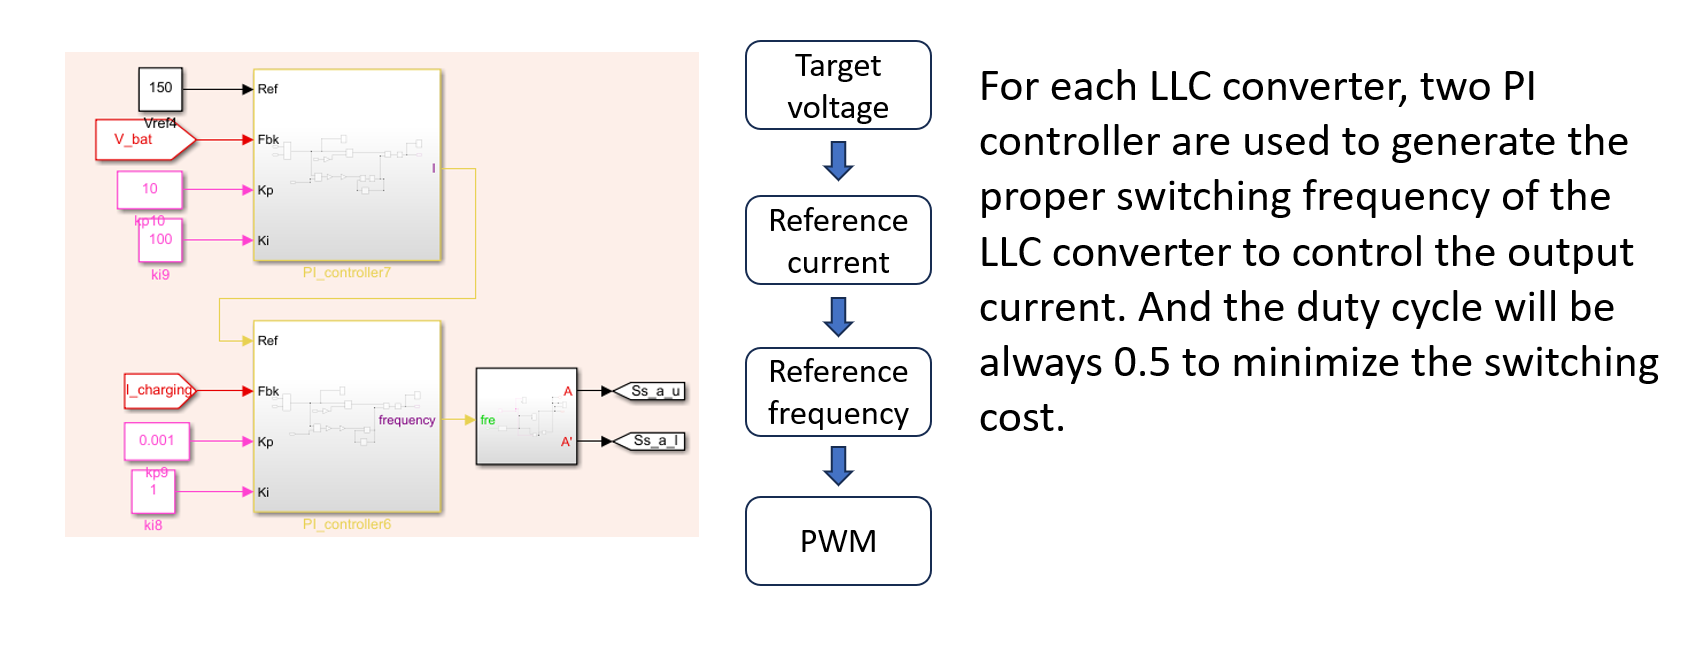

Click the **Run** button below, and once the simulation is complete **(this may take a few minutes)**, you will get the following four plots below:

- DC output voltage and battery current

- output power

- state of charge(SOC)

- battery terminal voltage

 
runmodel_isolated()

**Constant current charging stage configuration.**

### 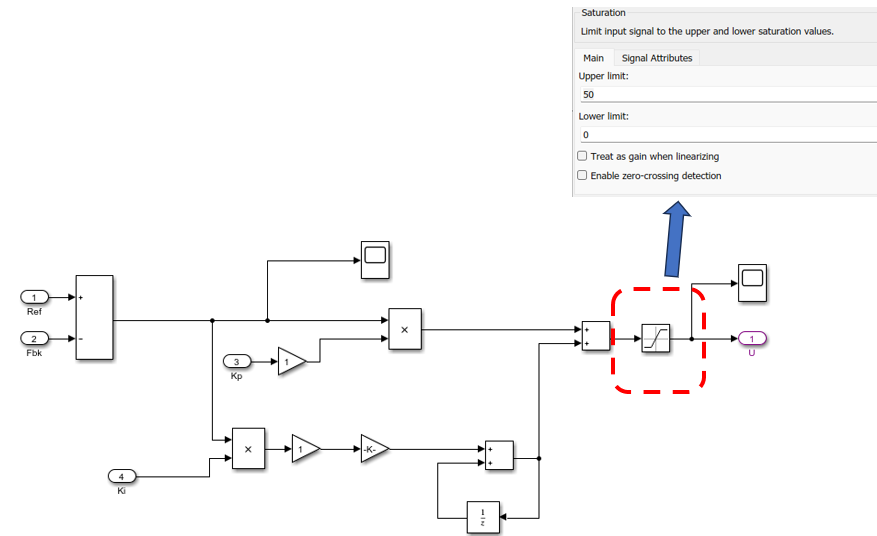

### Inverter and DC Bus Control

Inverter control includes two major parts: **current and voltage controller **and **duty cycle generation **. 

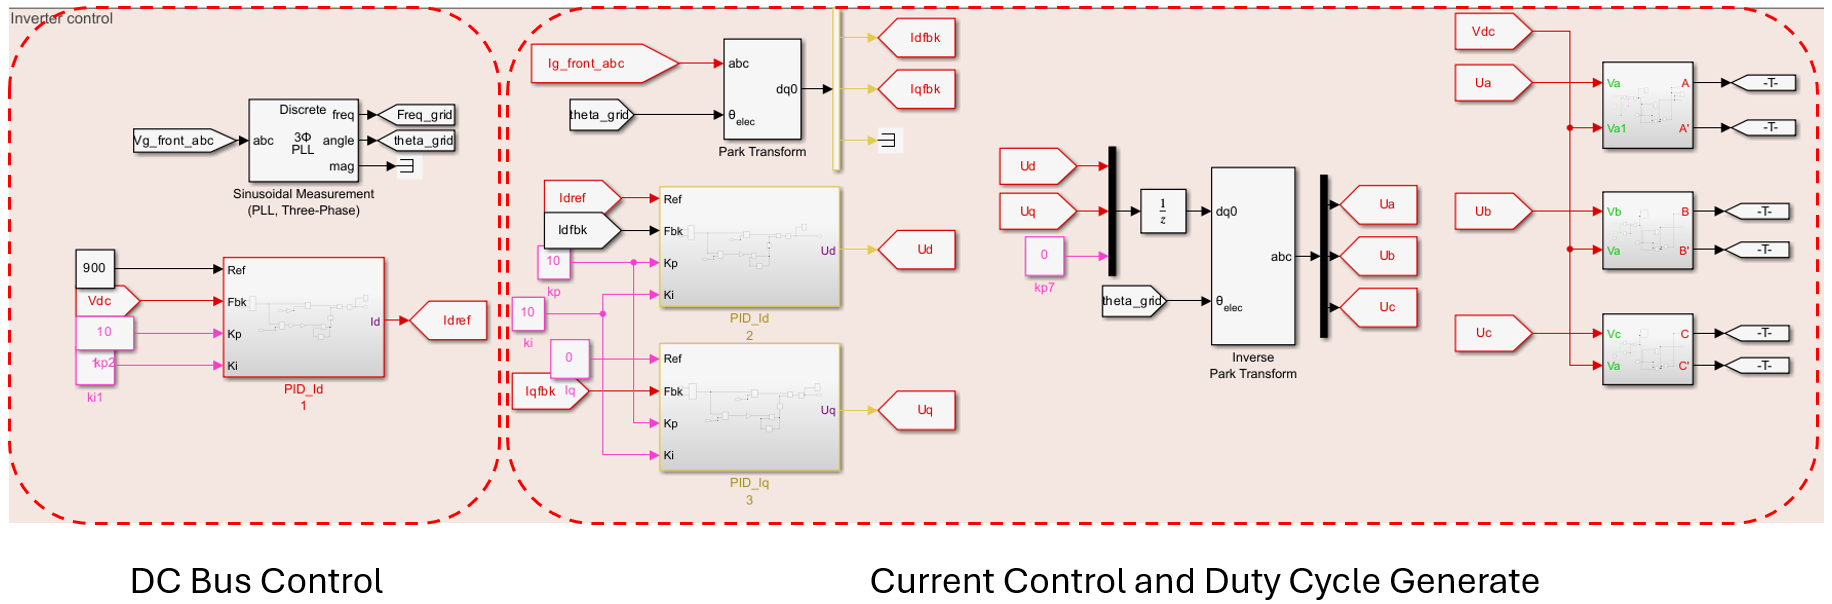

To understand the above three controllers further, select from the drop down menu below.

controller("No Selection")

## Analyzing the Results

Now, go to the model and run it, if you haven't do so already. After the simulation is complete **(this may take a few minutes)**, open the scopes to see the results. 

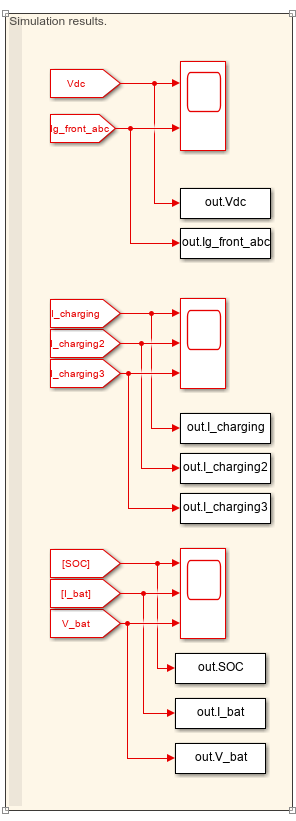

In this model, the viewers are encouraged to change the** initial SOC** of the battery to find the **constant current** and **constant voltage** stages.

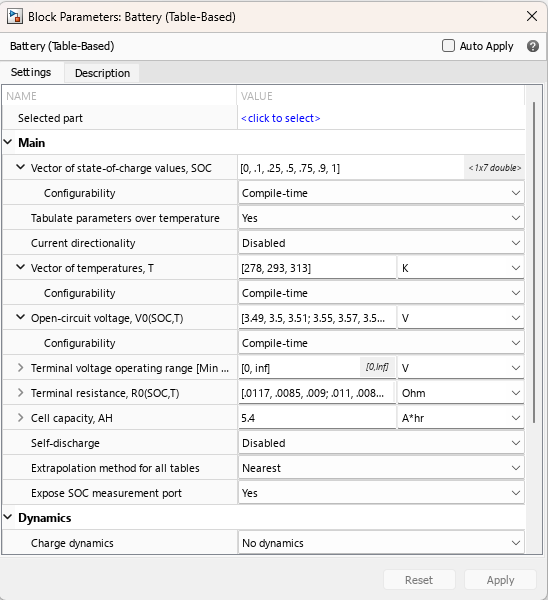

With the menu below, you can check reference simulation results provided for your convenience.

result("No Selection")

## Exercise

 **Exercise 1. What is the difference between isolated and non-isolated charger?**

exerciseSol1(...
     false, ...
   false);
 

 **Exercise 2. What is the final control target in LLC resonate converter?**

exerciseSol2(...
     false, ...
   false,...
  false);
 

 **Exercise 3 Check the simulation result of the model and try to increase the charging current, if the charging current is too high what might happen?**

exerciseSol3(...
     false, ...
   false,...
   false);
 

function switchRectifier(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "battery" "Grid" "Threedc"])}
end
clf;
if opt == "No Selection"
else
    if opt == "battery"
        rect = imread("Images/battery.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "Grid"
        rect = imread("Images/grid.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "Threedc"
        rect = imread("Images/LLC.png");
        imshow(rect, 'Interpolation', 'bilinear');
  
    end
end
end


function controller(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "DCbus control" "Inverter control" "SPWM"])}
end
clf;
if opt == "No Selection"
else
    if opt == "Inverter control"
        rect = imread("Images/controller.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "SPWM"
        rect = imread("Images/SPWM.png");
        imshow(rect,"Interpolation","bilinear");
    elseif opt == "DCbus control"
        rect = imread("Images/dcbus.png");
        imshow(rect,"Interpolation","bilinear");
    end
end
end

function result(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "Grid" "Battery" "Converter"])}
end
clf;
if opt == "No Selection"
else
    if opt == "Grid"
        rect = imread("Images/result1.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "Battery"
        rect = imread("Images/Result2.png");
        imshow(rect,"Interpolation","bilinear");
     elseif opt == "Converter"
        rect = imread("Images/Result3.png");
        imshow(rect,"Interpolation","bilinear");
        
    end
end
end





function exerciseSol1(A,B)
   
    arguments
        A (1,1) logical
        B (1,1) logical
        
    end

    if ~any([A B])
        warning("Please select all that apply!")
    elseif A&&B
        disp("Correct!")
    else 
        warning("Incorrect. Please review the circuit section again.")
    end
end

function exerciseSol2(A,B,C)
   
    arguments
        A (1,1) logical
        B (1,1) logical
        C (1,1) logical
        
    end

    if ~any([A B C])
        warning("Please select an answer!")
    elseif A+B+C > 1
        warning("Please select only one answer")
    elseif B
        disp("Correct!")
    else 
        warning("Incorrect. Please review the control section again")
    end
end
function exerciseSol3(A,B,C)
 
    arguments
        A (1,1) logical
        B (1,1) logical
        C (1,1) logical
    end

    if ~any([A B C])
        warning("Please select an answer!")
    elseif A+B+C > 1
        warning("Please select only one answer")
    elseif C
        disp("Correct!")
    else 
        warning("Incorrect.")
    end
end

function showpic1(A)
   
    arguments
        A (1,1) logical   
    end
    clf;
    if A
        rect = imread("Images/CC.png");
        imshow(rect,'Interpolation',"bilinear");
    else 
    end
end
function showpic2(A)
   
    arguments
        A (1,1) logical   
    end
    clf;
    if A
        rect = imread("Images/CV.png");
        imshow(rect,'Interpolation',"bilinear");
    else 
    end
end


function runmodel_isolated()

    warning('off', 'all'); 
    
    simOut = sim('Isooffboard_SSC.slx'); 
    out = simOut;

    try

        if isa(out.tout, 'timeseries')
            time = out.tout.Data;
        else
            time = out.tout;
        end

        if isa(out.Vdc, 'timeseries')
            vdc_val = squeeze(out.Vdc.Data);
        else

            vdc_val = squeeze(out.Vdc);
        end
        
        if isa(out.I_bat, 'timeseries')
            ibat_val = squeeze(out.I_bat.Data);
        else
            ibat_val = squeeze(out.I_bat);
        end

        if isa(out.SOC, 'timeseries')
            soc_val = squeeze(out.SOC.Data);
        else
            soc_val = squeeze(out.SOC);
        end
        
        if isa(out.V_bat, 'timeseries')
            vbat_val = squeeze(out.V_bat.Data);
        else
            vbat_val = squeeze(out.V_bat);
        end
        
        disp('✅ Data extraction complete. Proceeding to plot...');

        figure('Position', [100, 100, 1000, 800]);

        subplot(2,2,1); 

        plot(time, vdc_val, 'b', time, ibat_val, 'r', 'LineWidth', 1.2);
        title('DC Output Voltage and Battery Current');
        xlabel('Time (s)'); ylabel('Value');
        legend('V_{dc}', 'I_{bat}'); grid on;

        subplot(2,2,2); 
        plot(time, vdc_val .* ibat_val, 'k', 'LineWidth', 1.2);
        title('Output Power'); xlabel('Time (s)'); ylabel('Power (W)'); grid on;

        subplot(2,2,3); 
        plot(time, soc_val, 'g', 'LineWidth', 1.2);
        title('State of Charge (SOC)'); xlabel('Time (s)'); ylabel('%'); grid on;

        subplot(2,2,4); 
        plot(time, vbat_val, 'm', 'LineWidth', 1.2);
        title('Battery Terminal Voltage'); xlabel('Time (s)'); ylabel('V'); grid on;


    catch ME
        disp('❌ Error occurred during plotting:');
        disp(['MATLAB Error Message: ' ME.message]);
        disp('---');
        disp('**FINAL ACTION REQUIRED:** The issue is definitively related to data format inconsistency.');
        disp('Please manually inspect your Simulink model:');
        disp('1. Open **Isooffboard_SSC.slx**.');
        disp('2. For all "To Workspace" blocks and the "Outport" block that outputs time, **set "Save format" to Array**. This is the cleanest fix.');
    end
end